**Statistical Methods**

**Luis Mario Bres Castro**

**Lab 6: Frecuency Modulated Sinusoid Signal **

**Time-Frequency transform: Spectogram**

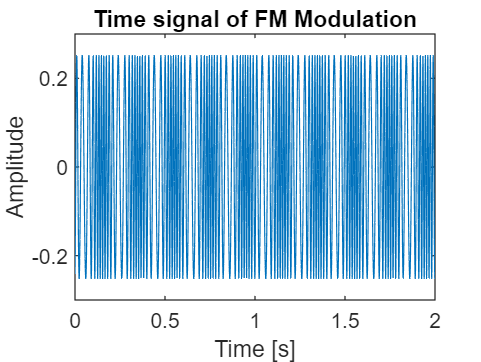

% pmlibRootDir = '/Users/luisbres/Desktop/Spring 2022/StatisticalMethods';
% addpath(genpath(pmlibRootDir),"-begin");
%NOTE Need to use relative, not absolute, path
addpath ..
%Signal Parameters
A=10; 
b=5;
f0=50;
f1=5;
psi=0;

%Instantaneous phase
%I(t)=2*pi*f0*t+b*cos(2*pi*f0*t)
%dI/dt=2*pi*f0-2*pi*f0*b*sin(2*pi*f0*t)
%f(1)=2*pi*f0(1-b*sin(2*pi*f0))

%Time samples 
maxFreq=2*pi*f0*(1-b*sin(2*pi*f0));
samplFreq = 5*maxFreq;
samplIntrvl = 1/samplFreq;
t=0:samplIntrvl:2;
% Number of samples
nSamples = length(t);
%Generate Signal
SigVec = FMSigGen(t,A,b,f0,f1,psi);
plot(t,SigVec)
title('Time signal of FM Modulation')
xlabel('Time [s]')
ylabel('Amplitude')

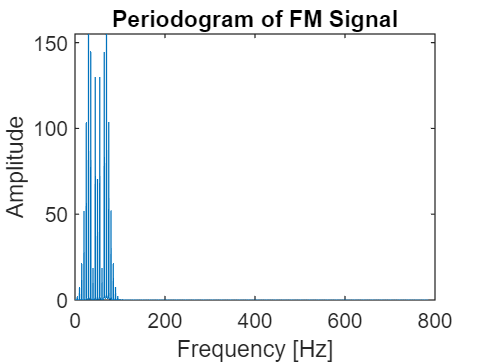


%Plot the periodogram

%Length of data 
dataLen = t(end)-t(1);
%DFT sample corresponding to Nyquist frequency
kNyq = floor(nSamples/2)+1;
% Positive Fourier frequencies
posFreq = (0:(kNyq-1))*(1/dataLen);
% FFT of signal
fftSig = fft(SigVec);
% Discard negative frequencies
fftSig = fftSig(1:kNyq);

%Plot periodogram
figure;
plot(posFreq,abs(fftSig));
title('Periodogram of FM Signal')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

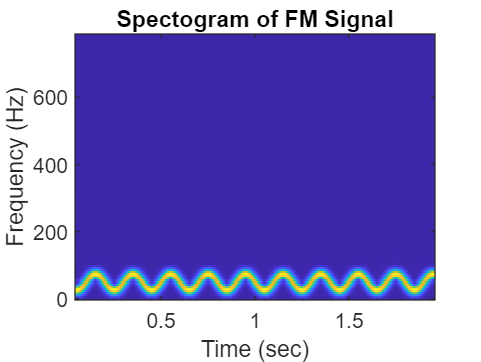


%Plot a spectrogram
%From testcrcbgenqcsig.m

[S,F,T]=spectrogram(SigVec,128,127,[],samplFreq);
figure;
imagesc(T,F,abs(S)); axis xy;
xlabel('Time (sec)');
ylabel('Frequency (Hz)');
title('Spectogram of FM Signal')